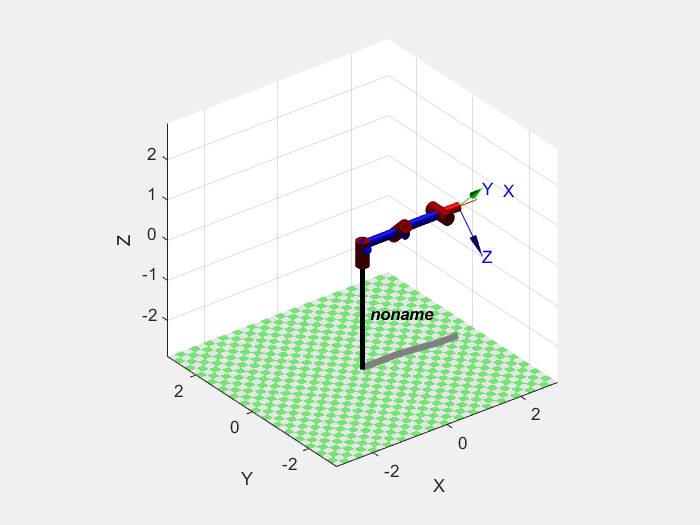

%标准D-H
%Link(D-H,option)
%D-H=[theta D A alpha sigma]
L1=Link([0 0.2 1 pi/4 0],'standard');
L2=Link([0 0.2 1 pi/4 0],'standard');
L3=Link([0 0 0.5 pi/4 0],'standard');
robot=SerialLink([L1 L2 L3]);%建立连杆机器人
robot.plot([0 0 0]) %显示并赋值三个theta变量均为0

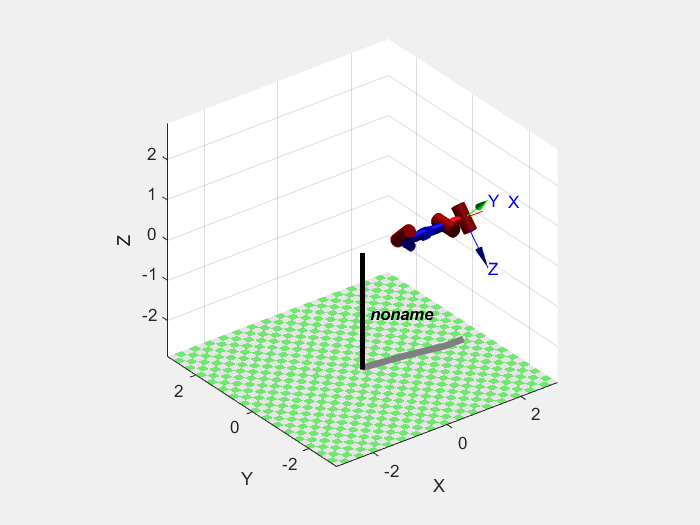

%改进D-H
%D-H=[thetai Di Ai-1 alphai-1 sigma]
L1=Link([0 0.2 1 pi/4 0],'modified');
L2=Link([0 0.2 1 pi/4 0],'modified');
L3=Link([0 0 0.5 pi/4 0],'modified');
robot=SerialLink([L1 L2 L3]);%建立连杆机器人
robot.plot([0 0 0]) %显示并赋值三个theta变量均为0

%例4.1
L1=Link([0 0.138 0 -pi/2])

 
L1 = 
Revolute(std): theta=q, d=0.138, a=0, alpha=-1.5708, offset=0


L1.type()

ans = 'R'

L1.theta

ans = 0

L1.d

ans = 0.1380

L1.a

ans = 0

L1.alpha

ans = -1.5708

L1.offset

ans = 0

%例4.2
clear
clc
L1=Link([pi/4 0 0 0 0],'modified');
L2=Link([pi/2 0.2 0.1 0 0],'modified');
L3=Link([0 0.1 0.2 0 0],'modified');
robot=SerialLink([L1 L2 L3]);
robot.display();

 
robot = 
 
noname:: 3 axis, RRR, modDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|          0|          0|
|  2|         q2|        0.2|        0.1|          0|          0|
|  3|         q3|        0.1|        0.2|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


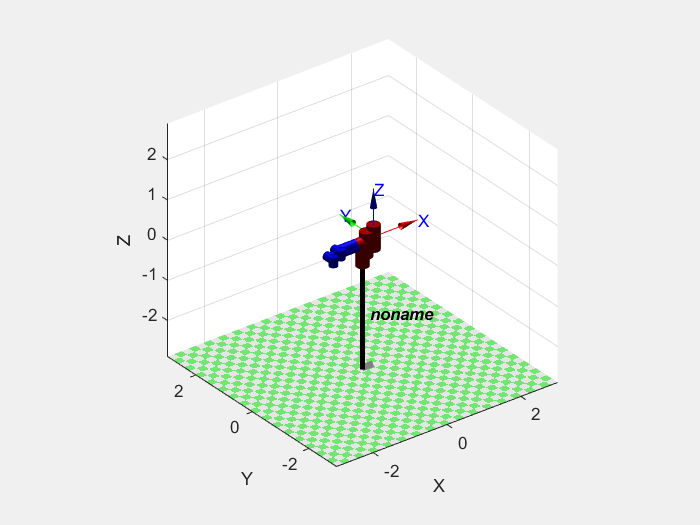

theta=[0 0 0];
robot.plot(theta);

%例4.3
L1=Link('d',0,'a',0,'alpha',pi/2);
L2=Link('d',0,'a',0.5,'alpha',0,'offset',pi/2);
L3=Link('d',0,'a',0,'alpha',pi/2,'offset',pi/4);
L4=Link('d',1,'a',0,'alpha',-pi/2);
L5=Link('d',0,'a',0,'alpha',pi/2);
L6=Link('d',1,'a',0,'alpha',0);
robot=SerialLink([L1 L2 L3 L4 L5 L6]);
robot.display();

 
robot = 
 
noname:: 6 axis, RRRRRR, stdDH, slowRNE                          
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|     1.5708|          0|
|  2|         q2|          0|        0.5|          0|     1.5708|
|  3|         q3|          0|          0|     1.5708|   0.785398|
|  4|         q4|          1|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          1|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


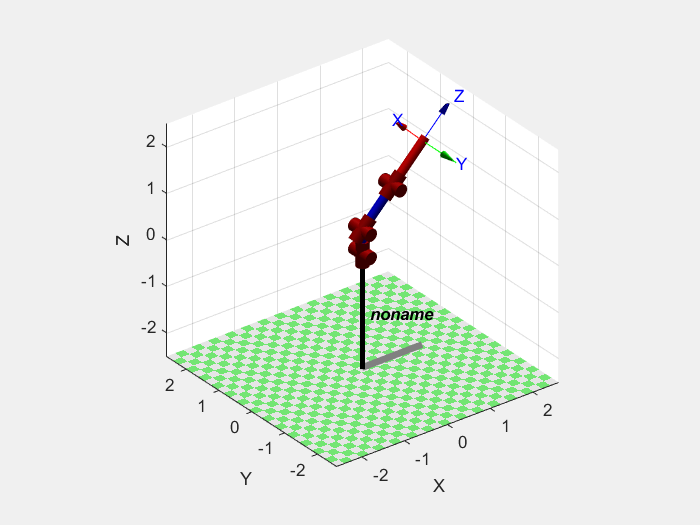

theta=[0 0 0 0 0 0];
robot.plot(theta);

%机器人示教
clear
L1=Link([0 0.4 0.025 pi/2 0]);
L2=Link([pi/2 0 0.56 pi/2 0]);
L3=Link([0 0 0.035 pi/2 0]);
L4=Link([0 0.515 0 pi/2 0]);
L5=Link([pi 0 0 pi/2 0]);
L6=Link([0 0.08 0 0 0]);
robot=SerialLink([L1 L2 L3 L4 L5 L6],'name','man');
robot.plot([0 pi/2 0 0 pi 0]);
robot.display();

 
robot = 
 
man:: 6 axis, RRRRRR, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|        0.4|      0.025|     1.5708|          0|
|  2|         q2|          0|       0.56|     1.5708|          0|
|  3|         q3|          0|      0.035|     1.5708|          0|
|  4|         q4|      0.515|          0|     1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|       0.08|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


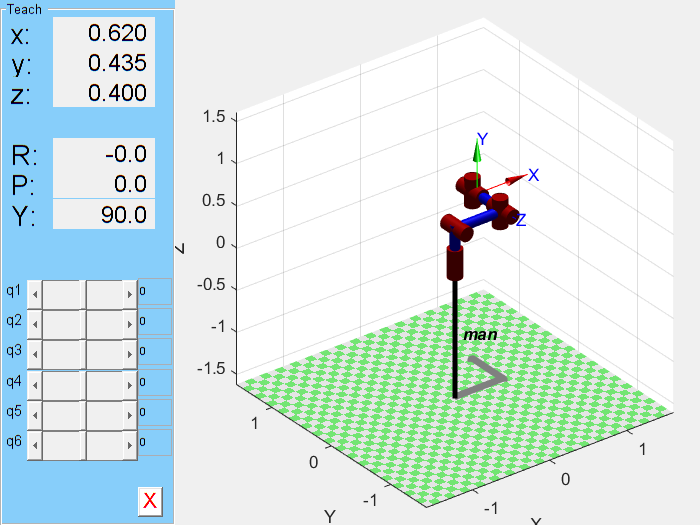

teach(robot);

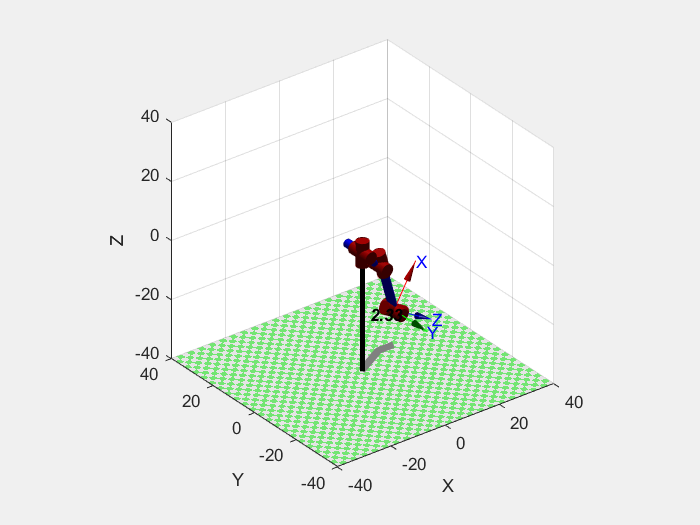

%教材P81 习题2.33
L1=Link('d',0,'a',0,'alpha',-pi/2);
L2=Link('d',6,'a',15,'alpha',0);
L3=Link('d',0,'a',1,'alpha',-pi/2);
L4=Link('d',18,'a',0,'alpha',pi/2);
L5=Link('d',0,'a',0,'alpha',-pi/2);
L6=Link('d',0,'a',0,'alpha',0);
robot=SerialLink([L1 L2 L3 L4 L5 L6],'name','2.33');
robot.plot([0 pi/4 -pi/3 0 -pi/4 0]);% theta3的数值略有改动

robot.display();

 
robot = 
 
2.33:: 6 axis, RRRRRR, stdDH, slowRNE                            
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|          0|          0|    -1.5708|          0|
|  2|         q2|          6|         15|          0|          0|
|  3|         q3|          0|          1|    -1.5708|          0|
|  4|         q4|         18|          0|     1.5708|          0|
|  5|         q5|          0|          0|    -1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 
